## Problem Symmetrical Short Circuit 7

Consider a simple power system. 

            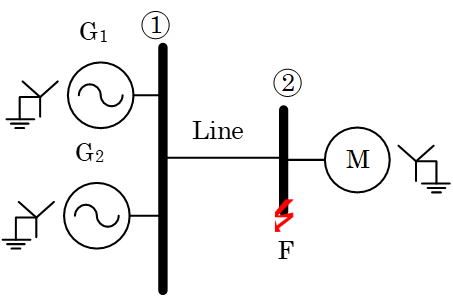                 

It consists of two synchronous generators (G1 and G2) connected through a transmission tine to a synchronous motor (M). The reactances of each generator are: *X**g*= 0.82 pu, *X’**g* = 0.70pu, *X”**g* =0.20 pu; the reactances of the motor are: *X**m* = 1.2 pu, *X’**m *= 0.95pu, *X”m *= 0.36 pu, and the reactance of transmission line is *X**L* = 0.48 pu. All the per-unit values are defined on the same bases. A bolted (*Z**f* = 0) three-phase short circuit occurs at the terminals of the motor when the voltage on its terminals is Vpf = 0.90 pu and the current provided by each generator is *I**g*1 = (0.70∠20°)pu, and *I**g*2 = (0.80∠-42°)pu. 

 Calculate the current internal EMF of each machine (G1, G2 and M) previous to the fault                                                                          

Calculate the subtrasient current contribution to the short circuit of each generator (*I”g*1and *I”**g*2) and the motor (*I”**m*) during the fault condition (use EMF method)

Calculate the subtrasient short-circuit current (*I”**f*) at the terminals of the motor (Use EMF method)                                                              

Calculate the subtrasient short-circuit current (*I”**f*) at the terminals of the motor (Use Thevenin method)        

Created by: Professor Francisco Gonzalez-Longatt, May 2020, [fglongatt@fglongatt.org](mail: fglongatt@fglongatt.org) 

Github: [https://github.com/fglongatt/Fault_Analysis](https://github.com/fglongatt/Fault_Analysis)

Reseach Gate: [https://www.researchgate.net/project/Power-System-Analysis-6](https://www.researchgate.net/project/Power-System-Analysis-6) 

clc
clear
Ig1 = 0.70 * exp (i * 20 *pi/180);
Ig2 = 0.80 * exp (i * -42 *pi/180);
Xm = 1.2

Xm = 1.2000

Xg = 0.36

Xg = 0.3600

X1g = 0.70

X1g = 0.7000

X2g = 0.20

X2g = 0.2000

Xm = 1.2

Xm = 1.2000

X1m = 0.95

X1m = 0.9500

X2m = 0.36

X2m = 0.3600

XL = 0.48

XL = 0.4800

Vpf = 0.90

Vpf = 0.9000

Initially, the situation is depicted in the following single line diagram:

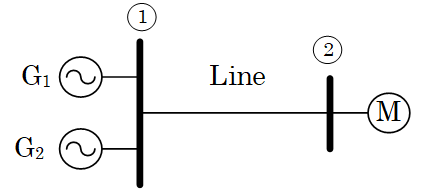

The equivalent circuit previous to the fault results:

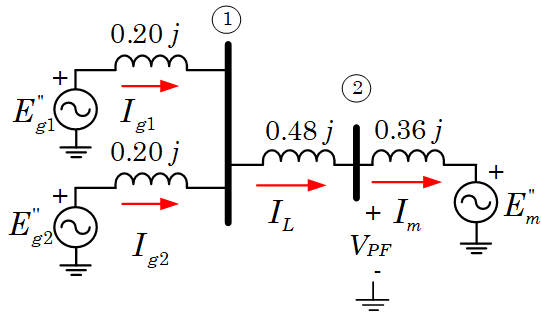                          

As the currents provided by the generators are known. 

fprintf(' Ig1 = (%5.5f + j%5.5f) pu',real(Ig1),imag(Ig1))

 Ig1 = (0.65778 + j0.23941) pu

fprintf(' Ig1 = (%5.5f < %5.5f) pu',abs(Ig1),angle(Ig1)*180/pi)

 Ig1 = (0.70000 < 20.00000) pu

fprintf(' Ig2 = (%5.5f + j%5.5f) pu',real(Ig2),imag(Ig2))

 Ig2 = (0.59452 + j-0.53530) pu

fprintf(' Ig2 = (%5.5f < %5.5f) pu',abs(Ig2),angle(Ig2)*180/pi)

 Ig2 = (0.80000 < -42.00000) pu

**During pre-fault conditions**, the KCL is applied a node 1:

Im = Ig1 + Ig2;
fprintf(' Im = (%5.5f + j%5.5f) pu',real(Im),imag(Im))

 Im = (1.25230 + j-0.29589) pu

fprintf(' Im = (%5.5f ∠ %5.5f°) pu',abs(Im),angle(Im)*180/pi)

 Im = (1.28678 ∠ -13.29389°) pu

Now, the internal voltage of each generator is calculated using KVL. At generator G1:

Eg1 = i * X2g * Ig1 + Vpf + i * XL * Im;
fprintf(' Eg1 = (%5.5f + j%5.5f) pu',real(Eg1),imag(Eg1))

 Eg1 = (0.99414 + j0.73266) pu

fprintf(' Eg1 = (%5.5f ∠ %5.5f°) pu',abs(Eg1),angle(Eg1)*180/pi)

 Eg1 = (1.23496 ∠ 36.38935°) pu

At generator G2:

Eg2 = i * X2g * Ig2 + Vpf + i * XL * Im;
fprintf(' Eg2 = (%5.5f + j%5.5f) pu',real(Eg2),imag(Eg2))

 Eg2 = (1.14909 + j0.72001) pu

fprintf(' Eg2 = (%5.5f ∠ %5.5f°) pu',abs(Eg2),angle(Eg2)*180/pi)

 Eg2 = (1.35603 ∠ 32.07086°) pu

At the motor M:

Em = Vpf - i * X2m * Im;
fprintf(' Em = (%5.5f + j%5.5f) pu',real(Em),imag(Em))

 Em = (0.79348 + j-0.45083) pu

fprintf(' Em = (%5.5f ∠ %5.5f°) pu',abs(Em),angle(Em)*180/pi)

 Em = (0.91261 ∠ -29.60378°) pu

**During fault conditions,**the new equivalent circuit previous to the fault results:

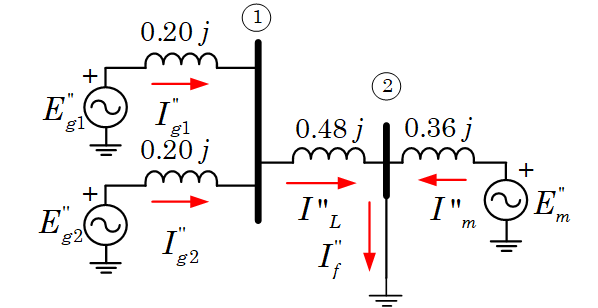

Using the EMF method, the motor contribution (*I**”**m*) is calculated as:

I2m = Em / (i * X2m);
fprintf(' Im = (%5.5f + j%5.5f) pu',real(I2m),imag(I2m))

 Im = (-1.25230 + j-2.20411) pu

fprintf(' Im = (%5.5f ∠ %5.5f°) pu',abs(I2m),angle(I2m)*180/pi)

 Im = (2.53503 ∠ -119.60378°) pu

The current contribution from G1 and G2 are calculated by using KVL: 

A=[i*(X2g + XL) i*XL; i*XL i*(X2g+XL)]

A =    0.0000 + 0.6800i   0.0000 + 0.4800i
   0.0000 + 0.4800i   0.0000 + 0.6800i


b =[Eg1; Eg2]

b =    0.9941 + 0.7327i
   1.1491 + 0.7200i


I = A^-1 * b

I =    0.6578 - 0.5364i
   0.5945 - 1.3112i


I2g1 = I(1);
I2g2 = I(2);
fprintf(' I2g1 = (%5.5f + j%5.5f) pu = (%5.5f ∠ %5.5f°) pu',real(I2g1),imag(I2g1), abs(I2g1),angle(I2g1)*180/pi)

 I2g1 = (0.65778 + j-0.53645) pu = (0.84880 ∠ -39.19852°) pu

fprintf(' I2g2 = (%5.5f + j%5.5f) pu = (%5.5f ∠ %5.5f°) pu',real(I2g2),imag(I2g2), abs(I2g2),angle(I2g2)*180/pi)

 I2g2 = (0.59452 + j-1.31117) pu = (1.43966 ∠ -65.60927°) pu

Finally, the fault current is calculated by using KCL:

I2L =  I2g1 + I2g2;
fprintf(' I2L = (%5.5f + j%5.5f) pu = (%5.5f ∠ %5.5f°) pu',real(I2m),imag(I2m), abs(I2m),angle(I2m)*180/pi)

 I2L = (-1.25230 + j-2.20411) pu = (2.53503 ∠ -119.60378°) pu

I2f = I2L +I2m;
fprintf(' I2f = (%5.5f + j%5.5f) pu = (%5.5f ∠ %5.5f°) pu',real(I2f),imag(I2f), abs(I2f),angle(I2f)*180/pi)

 I2f = (0.00000 + j-4.05172) pu = (4.05172 ∠ -90.00000°) pu

Solving Thevenin

Xp = X2g /2;
Xq = Xp + XL;
Xth = Xq * X2m/(Xq + X2m);
Zth = i * Xth

Zth = 0.0000 + 0.2221i

I2f = Vpf / Zth;
fprintf(' I2f = (%5.5f + j%5.5f) pu = (%5.5f ∠ %5.5f°) pu',real(I2f),imag(I2f), abs(I2f),angle(I2f)*180/pi)

 I2f = (0.00000 + j-4.05172) pu = (4.05172 ∠ -90.00000°) pu